# Análisis de activación de reglas de VRUs

## Regla MovinPed escenario baja densidad 


fid=fopen('TxNodes-MovinPed-S11-V0-DEN-0.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';


ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        if LD_Nodes(i,4)>=((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     27    28    28    28    28    28    28    29    30    30    30    30    30    30    30    31    31    32    32    32
    35    36    36    36    36    36    38    38    38    37    37    38    38    38    39    39    40    40    41    41
   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102
    44    44    43    43    44    43    43    43    43    43    41    42    42    42    43    42    42    43    43    43


sum(ind2)

ans =    208   210   209   209   210   209   211   212   213   212   210   212   212   212   214   214   215   217   218   218



mean(sum(ind2))

ans = 212.2500

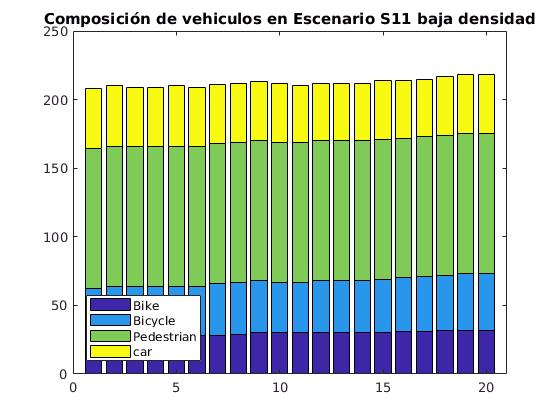



figure (2)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S11 baja densidad');
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


ind3

ind3 =     23    23    23    23    23    23    23    23    23    23    23    23    23    23    23    23    23    23    23    23
    31    31    31    30    30    30    30    30    29    28    28    28    28    28    28    28    28    28    28    28
    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sum(ind3)

ans =    144   144   144   143   143   143   143   143   142   141   141   141   141   141   141   141   141   141   141   141



mean(sum(ind3))

ans = 142

## Proporción de nodos transmisores (en los 20 seg de simulación) / nodos en el escenario 

ind3./ind2

ans =     0.8519    0.8214    0.8214    0.8214    0.8214    0.8214    0.8214    0.7931    0.7667    0.7667    0.7667    0.7667    0.7667    0.7667    0.7667    0.7419    0.7419    0.7188    0.7188    0.7188
    0.8857    0.8611    0.8611    0.8333    0.8333    0.8333    0.7895    0.7895    0.7632    0.7568    0.7568    0.7368    0.7368    0.7368    0.7179    0.7179    0.7000    0.7000    0.6829    0.6829
    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mean((ind3./ind2),2)

ans =     0.7790
    0.7688
    0.8824
         0


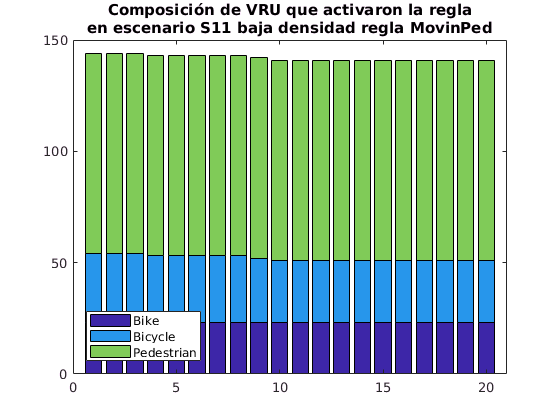


figure (3)
bar(ind3','stacked')
title({'Composición de VRU que activaron la regla','en escenario S11 baja densidad regla MovinPed'})
legend('Bike','Bicycle','Pedestrian','Location','SouthWest');
xlim([0 21])

## Regla MovinPed escenario alta densidad 



fid=fopen('TxNodes-MovinPed-S11-V0-DEN-1.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';


ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        if LD_Nodes(i,4)>=((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     36    36    37    38    38    38    39    38    39    39    40    40    41    41    42    42    43    44    44    44
    68    68    68    68    68    68    67    67    67    67    67    67    67    67    68    67    66    67    67    67
   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212
    78    78    77    76    76    76    76    75    75    75    74    74    73    73    72    72    71    70    71    71


sum(ind2)

ans =    394   394   394   394   394   394   394   392   393   393   393   393   393   393   394   393   392   393   394   394



mean(sum(ind2))

ans = 393.4000

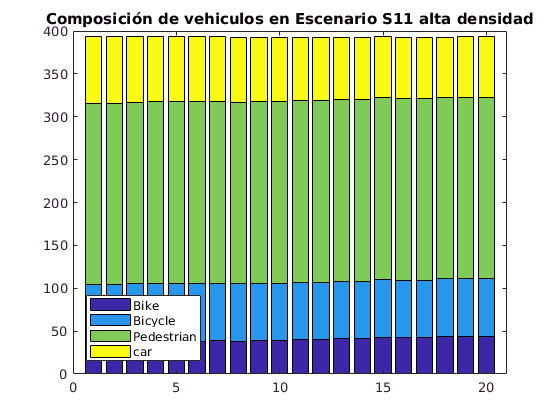



figure (2)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S11 alta densidad');
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


ind3

ind3 =     34    34    34    34    34    34    34    33    33    33    33    33    33    33    33    33    33    33    33    33
    65    65    65    65    65    65    64    64    64    64    64    64    63    63    63    62    61    61    61    61
   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sum(ind3)

ans =    240   240   240   240   240   240   239   238   238   238   238   238   237   237   237   236   235   235   235   235



mean(sum(ind3))

ans = 237.8000

## Proporción de nodos transmisores (en los 20 seg de simulación) / nodos en el escenario 

ind3./ind2

ans =     0.9444    0.9444    0.9189    0.8947    0.8947    0.8947    0.8718    0.8684    0.8462    0.8462    0.8250    0.8250    0.8049    0.8049    0.7857    0.7857    0.7674    0.7500    0.7500    0.7500
    0.9559    0.9559    0.9559    0.9559    0.9559    0.9559    0.9552    0.9552    0.9552    0.9552    0.9552    0.9552    0.9403    0.9403    0.9265    0.9254    0.9242    0.9104    0.9104    0.9104
    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651    0.6651
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mean((ind3./ind2),2)

ans =     0.8387
    0.9427
    0.6651
         0


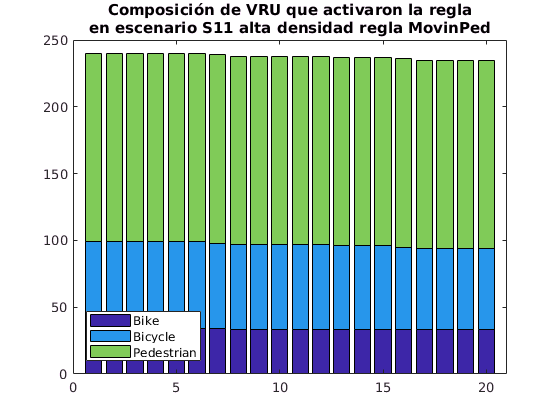


figure (3)
bar(ind3','stacked')
title({'Composición de VRU que activaron la regla','en escenario S11 alta densidad regla MovinPed'})
legend('Bike','Bicycle','Pedestrian','Location','SouthWest');
xlim([0 21])